# Robotics II

Midterm April 26 2018

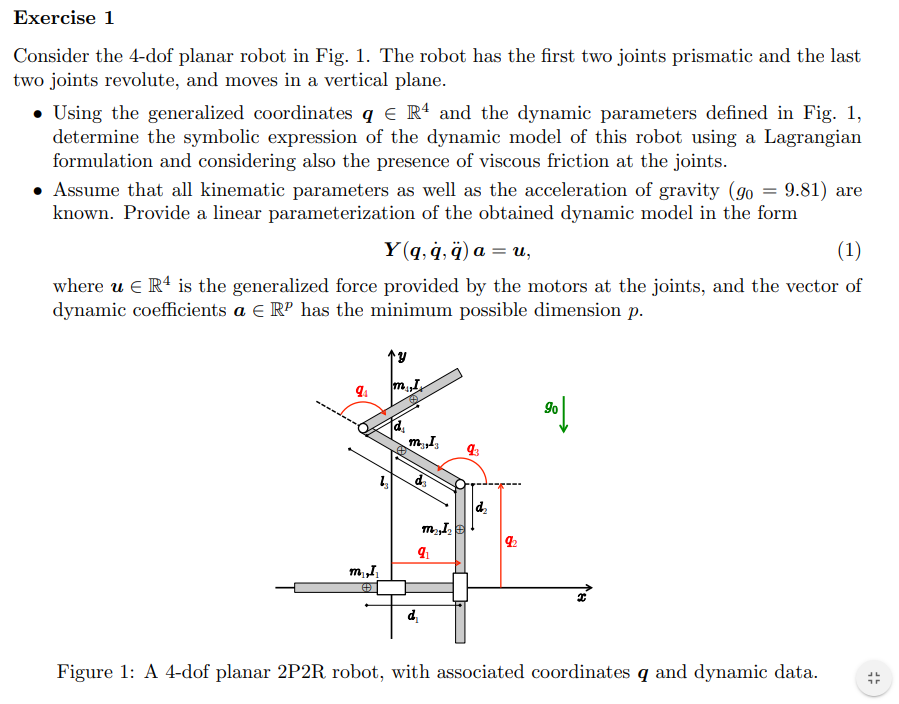

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [1,1,0,0];
% n = length(sigma);
% t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% qd = sym('qd', [n 1],'real');
% qdd = sym('qdd', [n 1],'real'); 
% 
% dc = sym('dc', [n 1],'real');
% k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% I = sym('I', [n 1],'real');
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% isMotor=0;

% % %Insert manually the global positions of the centers of mass
% % pc(:,1) = [q(1) 0];
% % pc(:,2) = [q(1)+k(1)+dc(2)*cos(q(2)), dc(2)*sin(q(2))];
% % pc(:,3) = [q(1)+k(1)+l(2)*cos(q(2))+dc(3)*cos(q(2)+q(3)), l(2)*sin(q(2))+dc(3)*sin(q(2)+q(3))]
% % [pct,qt]=ToTimedep(pc,n,'t','q')
% % vct = diff(pct,t)
% % [vc,q_d1,vc_short]=shortdiff(vct,sym2cell(qt),t,true,1,qd)%,[qd,qdd])
% % w =[0, qd(2), qd(2)].';
% % % for i=1:n
% % %  T(i) = (1/2)*m(i)*(vc(:,i).'*vc(:,i)) + (1/2)*w(i)*I(i)*w(i);
% % % end
% % % KE = sum(T.')
% % % 
% % 

%  
% R2Robot=['pprr';'xyxx';[1,1,1,1]]       

% [Pc,vc,w,T,Ti,M] = getGenericPC(R2Robot,l,q,qd,dc,m,I)
% 

## minimal parametrization

%  [C,cac,Csubs,S] = getCs(M,q,qd);
%  [Msubs, dynamicParameters, a] = getDynamicParameters(M,q,l',2)%l')
%  [Csubs,cacsubs,Csubssubs,Ssubs] = getCs(Msubs,q,qd)
% 

## manual minimization

% % Msubs_2=subs(Msubs,a(7),dynamicParameters(7))
% % dynamicParameters
% % unique(Msubs_2(find(has(Msubs_2,dynamicParameters(7))) ))
% %  
% 

## gratvity computing

%  %viscous_Friction====>fv;
% [g_q, PE, U,g_q_short,PE_short,fv] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor);
%  [g_qsubs, dynamicParametersG, aG] = getDynamicParameters(g_q(1:end),q,[g0],2)
%  [g_qsubs_,dynamicParameters,a] = matchingFuncs(g_qsubs,dynamicParameters,dynamicParametersG,a,aG);
%  
%  dynamicParameters_=[dynamicParameters;fv]
%  au=sym('a',[10,1],'real')
%  u_subs=Msubs*qdd+cacsubs+g_qsubs_+au(7:end).*qd
%   [Yu, Yushort] = getLinearParametrization(u_subs,au)
% simplify(u_subs-Yu*au)


## exercise 2

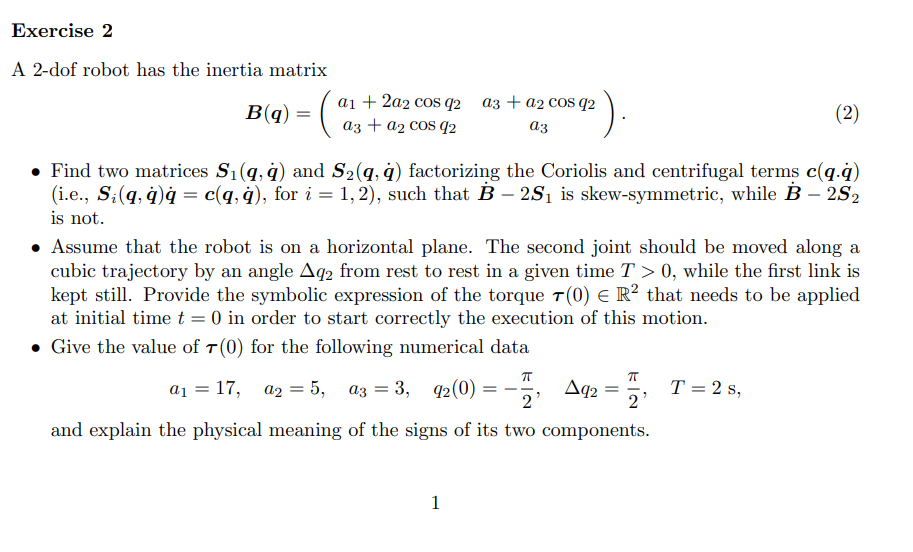

% This part is isolated from previous section
clear;clc

% syms k q1(t) q2(t) q3(t)
sigma = [1,0];
n = length(sigma);
t = sym('t', 'real');
q = sym('q', [n 1],'real');
q0 = sym('q0', [n 1],'real');
qf = sym('qf', [n 1],'real');

a = sym('a', [3 1],'real');
T = sym('T', [1 1],'real');
t_ = sym('t_','real');

qd = sym('qd', [n 1],'real');
qdd = sym('qdd', [n 1],'real'); 
qdd0 = sym('qdd0', [n 1],'real'); 

dc = sym('dc', [n 1],'real');
k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
I = sym('I', [n 1],'real');
g0 = sym('g0','real');
g=[0,-g0,0]';
isMotor=0;

% %Insert manually the global positions of the centers of mass
% pc(:,1) = [q(1) 0];
% pc(:,2) = [q(1)+k(1)+dc(2)*cos(q(2)), dc(2)*sin(q(2))];
% pc(:,3) = [q(1)+k(1)+l(2)*cos(q(2))+dc(3)*cos(q(2)+q(3)), l(2)*sin(q(2))+dc(3)*sin(q(2)+q(3))]
% [pct,qt]=ToTimedep(pc,n,'t','q')
% vct = diff(pct,t)
% [vc,q_d1,vc_short]=shortdiff(vct,sym2cell(qt),t,true,1,qd)%,[qd,qdd])
% w =[0, qd(2), qd(2)].';
% % for i=1:n
% %  T(i) = (1/2)*m(i)*(vc(:,i).'*vc(:,i)) + (1/2)*w(i)*I(i)*w(i);
% % end
% % KE = sum(T.')
% % 
% 

 
% R2Robot=['pr';'yx';[1,1]]    
Msubs=[a(1)+2*a(2)*cos(q(2)),a(3)+a(2)*cos(q(2));
        a(3)+a(2)*cos(q(2)),a(3)
        ]

$$Msubs = \left(\begin{array}{cc} a_{1}+2\,a_{2}\,\cos\left(q_{2}\right) & a_{3}+a_{2}\,\cos\left(q_{2}\right)\\ a_{3}+a_{2}\,\cos\left(q_{2}\right) & a_{3} \end{array}\right)$$

[Csubs,cacsubs,Csubssubs,S1] = getCs(Msubs,q,qd)

>> Getting  the Christoffel’sym. Might take a while...


Csubs = 1×2 cell array
    {2×2 sym}    {2×2 sym}


$$cacsubs = \left(\begin{array}{c} -a_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}\right)\\ a_{2}\,{{\mathrm{qd}}_{1}}^{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

Csubssubs = 1×2 cell array
    {2×2 sym}    {2×2 sym}


$$S1 = \left(\begin{array}{cc} -a_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right) & -a_{2}\,\sin\left(q_{2}\right)\,\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}\right)\\ a_{2}\,{\mathrm{qd}}_{1}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

svals=[a(2)*sin(q(2))*qd(1),0]';%% possible solution
% svals=[qd(1),0]';%% possible solution also works

[S0_,S_,S0v] = getGenericS0(q,qd,svals);

>> Getting  Generics S0...


S_ = struct with fields:
    s1_1: [1×1 sym]
    s2_1: [1×1 sym]


S_ = struct with fields:
    s1_2: [1×1 sym]
    s2_2: [1×1 sym]


$$ans = \left(\begin{array}{cc} -\frac{{\mathrm{qd}}_{2}\,s_{1,2}}{{\mathrm{qd}}_{1}} & s_{1,2}\\ -\frac{{\mathrm{qd}}_{2}\,s_{2,2}}{{\mathrm{qd}}_{1}} & s_{2,2} \end{array}\right)$$

$$ans = \left(\begin{array}{cc} s_{1,1} & -\frac{{\mathrm{qd}}_{1}\,s_{1,1}}{{\mathrm{qd}}_{2}}\\ s_{2,1} & -\frac{{\mathrm{qd}}_{1}\,s_{2,1}}{{\mathrm{qd}}_{2}} \end{array}\right)$$

$$ans = \left(\begin{array}{cc} -a_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right) & a_{2}\,{\mathrm{qd}}_{1}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$ans = \left(\begin{array}{cc} a_{2}\,{\mathrm{qd}}_{1}\,\sin\left(q_{2}\right) & -\frac{a_{2}\,{{\mathrm{qd}}_{1}}^{2}\,\sin\left(q_{2}\right)}{{\mathrm{qd}}_{2}}\\ 0 & 0 \end{array}\right)$$

S2=simplify(S1+S0v{1})

$$S2 = \left(\begin{array}{cc} -2\,a_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right) & -a_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)\\ a_{2}\,{\mathrm{qd}}_{1}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

## checking symmetry

[Msubsd,Mtsubsd,qt] = getM_dot(Msubs,q,qd)

>> Getting M dot. Might take a while...

var_set =

     []



$$Md = \left(\begin{array}{cc} -2\,a_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right) & -a_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)\\ -a_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

$$Msubsd = \left(\begin{array}{cc} -2\,a_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right) & -a_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)\\ -a_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

$$Mtsubsd = \left(\begin{array}{cc} -2\,a_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) & -a_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\\ -a_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) & 0 \end{array}\right)$$

$$qt = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

% Msubsd=subs(Msubsd,qd,svals)
simplify(expand(Msubsd-2*S1))

$$ans = \left(\begin{array}{cc} 0 & a_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}\right)\\ -a_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}\right) & 0 \end{array}\right)$$

simplify(expand(Msubsd-2*S2))

$$ans = \left(\begin{array}{cc} 2\,a_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right) & a_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)\\ -a_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}\right) & 0 \end{array}\right)$$

## cubic splitline

[spline_fun,Aw_fun,Aa_fun,Ajerk_fun,MaxsVal] = splinesD(2,1,[0 T],[q0(2) qf(2)],3,false)

NumJoints = 1

M = 1

v_init = 0

a_init = 0

v_end = 0

a_end = 0

ak = struct with fields:
    ak_1: [1×1 sym]
    ak_2: [1×1 sym]
    ak_3: [1×1 sym]


ans = 1×3 string array
    "0"    "3*q2 - 3*q1"    "2*q1 - 2*q2"


$$spline\_fun = q_{02}-\frac{{\mathrm{t\_}}^{2}\,\left(3\,q_{02}-3\,{\mathrm{qf}}_{2}\right)}{{T_{1}}^{2}}+\frac{{\mathrm{t\_}}^{3}\,\left(2\,q_{02}-2\,{\mathrm{qf}}_{2}\right)}{{T_{1}}^{3}}$$

$$spline\_fun = q_{02}-\frac{{\mathrm{t\_}}^{2}\,\left(3\,q_{02}-3\,{\mathrm{qf}}_{2}\right)}{{T_{1}}^{2}}+\frac{{\mathrm{t\_}}^{3}\,\left(2\,q_{02}-2\,{\mathrm{qf}}_{2}\right)}{{T_{1}}^{3}}$$

$$Aw\_fun = \frac{3\,{\mathrm{t\_}}^{2}\,\left(2\,q_{02}-2\,{\mathrm{qf}}_{2}\right)}{{T_{1}}^{3}}-\frac{2\,\mathrm{t\_}\,\left(3\,q_{02}-3\,{\mathrm{qf}}_{2}\right)}{{T_{1}}^{2}}$$

$$Aa\_fun = \frac{6\,\mathrm{t\_}\,\left(2\,q_{02}-2\,{\mathrm{qf}}_{2}\right)}{{T_{1}}^{3}}-\frac{2\,\left(3\,q_{02}-3\,{\mathrm{qf}}_{2}\right)}{{T_{1}}^{2}}$$

$$Ajerk\_fun = \frac{6\,\left(2\,q_{02}-2\,{\mathrm{qf}}_{2}\right)}{{T_{1}}^{3}}$$

MaxsVal = struct with fields:
     timepeak: [1×1 struct]
    PeakValue: [1×1 struct]


qdd20_=simplify(expand(subs(Aa_fun,t_,0)))

$$qdd20\_ = -\frac{6\,\left(q_{02}-{\mathrm{qf}}_{2}\right)}{{T_{1}}^{2}}$$

qdd202_=simplify(expand(subs(qdd20_,[q0(2),qf(2),T(1)],[-pi/2,0,2])))

$$qdd202\_ = \frac{3\,\pi }{4}$$

## the gravity only affects vertically for this reason doesn't appear

tao=Msubs*qdd+cacsubs

$$tao = \left(\begin{array}{c} {\mathrm{qdd}}_{1}\,\left(a_{1}+2\,a_{2}\,\cos\left(q_{2}\right)\right)+{\mathrm{qdd}}_{2}\,\left(a_{3}+a_{2}\,\cos\left(q_{2}\right)\right)-a_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}\right)\\ a_{2}\,\sin\left(q_{2}\right)\,{{\mathrm{qd}}_{1}}^{2}+{\mathrm{qdd}}_{1}\,\left(a_{3}+a_{2}\,\cos\left(q_{2}\right)\right)+a_{3}\,{\mathrm{qdd}}_{2} \end{array}\right)$$

tao0_=simplify(subs(tao,[qd;qdd],[0;0;0;qdd0(2)]))

$$tao0\_ = \left(\begin{array}{c} {\mathrm{qdd}}_{02}\,\left(a_{3}+a_{2}\,\cos\left(q_{2}\right)\right)\\ a_{3}\,{\mathrm{qdd}}_{02} \end{array}\right)$$

a_=[17,5,3];
tao02_=vpa(subs(tao0_,[a',q(2),qdd0(2)],[a_,-pi/2,qdd202_]))

$$tao02\_ = \left(\begin{array}{c} 7.0685834705770347865409476123789\\ 7.0685834705770347865409476123789 \end{array}\right)$$

## exercise 3

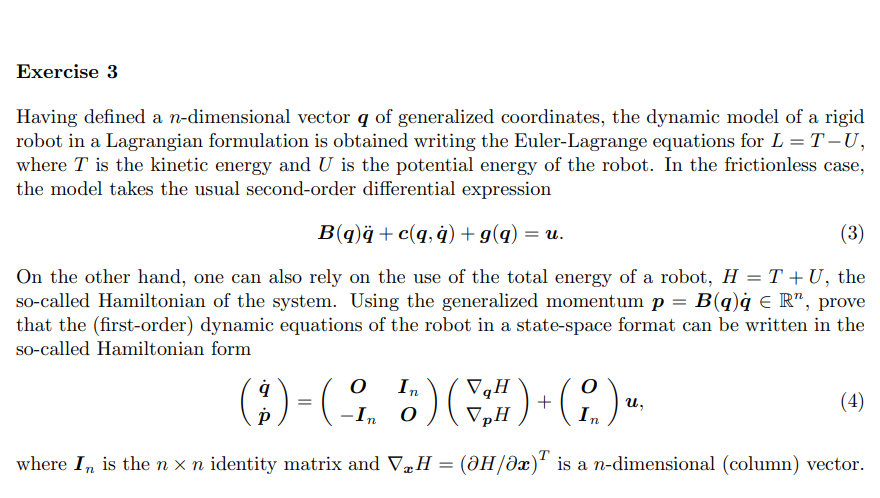

Ver examen ahha it is just a demostration

## Exercise 4

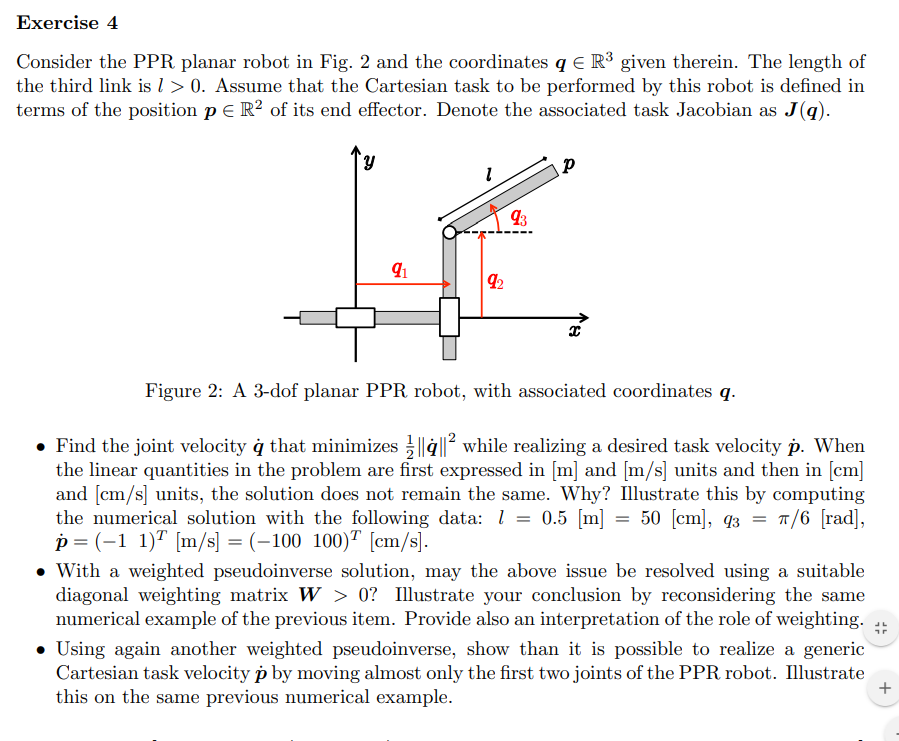

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [1,1,0];
% n = length(sigma);
% t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% qd = sym('qd', [n 1],'real');
% pd = sym('pd', [2 1],'real');
% 
% qdd = sym('qdd', [n 1],'real'); 
% 
% dc = sym('dc', [n 1],'real');
% k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% 
% m = sym('m', [n 1],'real');
% I = sym('I', [n 1],'real');
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% isMotor=0;

% %  
% lmeters_=[0.5,0.5,0.5]'
% q_=[q(1),q(2),pi/6]'
% pdotmeters_=[-1,1]'
% 
% lcm_=[50,50,50]'
% pdotcm_=[-100,100]'
% 
% varsreplace=[l;q;pd];
% varsreplacemeters_=[lmeters_;q_;pdotmeters_];
% varsreplacecm_=[lcm_;q_;pdotcm_];
% R2Robot=['ppr';'xyx';[1,1,1]]       

% % [Pc,vc,w,T,Ti,M] = getGenericPC(R2Robot,l,q,qd,dc,m,I)
% % % 
% % J=jacobian(Pc(:,end),q)
% xyonly=true;
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot] = getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % J_ps=subs()

## the simples way for minimize q dot is

% x_dot=[2,1]'
% J=[3,1,2;1.5,0.5,1]
% rank(J)
% J_ps=pinv(J)
% q_dot_star=J_ps*x_dot
% norm(q_dot_star)
% W=eye(3)
% W(1,1)=20
% % w_(1,1)=0
% % w_=0.5*q_dot_star'*w_*q_dot_star
% qdotstar=q_dot_star+pinv(J*W)*(x_dot-J*q_dot_star)
% norm(qdotstar)
% 
% % [qdotstarFinal,W] = SNSMethod2(V_,J_,q_dMax_')%,Qdotmin,Qdotdmax)
% 
% [J_pseudo_w,J__pseudo,W] = WeightedPseInverse(W,J,q,[])
% q_dot_star2=J_pseudo_w*x_dot
% norm(q_dot_star2)
% % 
% % qd_min=J_ps*pd
% % digits(4)
% % %meters
% % qd_minmeters_=vpa(subs(qd_min,varsreplace,varsreplacemeters_))
% % 
% % %cm
% % qd_mincm_=vpa(subs(qd_min,varsreplace,varsreplacecm_))
% 

## weighted pseudo inverse

% [J_pseudo_w,J__pseudo,W,Wvars] = WeightedPseInverse([],J,q,[1,1,0])
% 
% J_pseudo_w_=subs(J_pseudo_w,Wvars,l(3)^2)
% 
% qd_minW=J_pseudo_w_*pd
% digits(4)
% %meters
% qd_minmeters_=vpa(subs(qd_minW,varsreplace,varsreplacemeters_)) %m/s
% 
% %cm
% qd_mincm_=vpa(subs(qd_minW,varsreplace,varsreplacecm_)) %cm/s
% 
% J_pseudo_w_=subs(J_pseudo_w,Wvars,1000)
% 
% qd_minW=J_pseudo_w_*pd
% digits(4)
% %meters
% qd_minmeters_=vpa(subs(qd_minW,varsreplace,varsreplacemeters_)) %m/s
% 
% %cm
% qd_mincm_=vpa(subs(qd_minW,varsreplace,varsreplacecm_)) %cm/s









